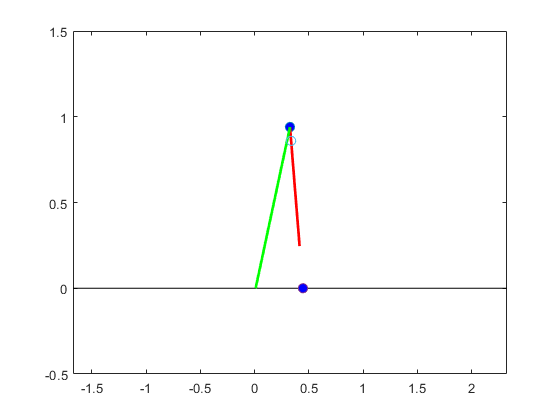

clear

L0 = 1; % [m]
alpha0 = 1.2; % angle at which swing leg touches the ground
m_M = 70; % hip mass [kg]
m_swLeg = 5; % [kg]
m_swFoot = 5; % [kg]
L_thigh = 0.7; % [m]
I_swLeg = (1/3)*m_swLeg*(L_thigh/2)^2; %
I_swFoot = m_swFoot*(L_thigh)^2; %
g = 9.81; % gravitational acc

k0 = 15696; % nominal leg stiffness [N/m]

load('C:\Matlab Workspace\5LinkWalk_Gain hand tuning\BA-202007171452-stable Copy - fixing ZMP\SLIPSL_Data\dc_comp2020-01-15-13-47.mat')

i = 13;
x_M = dc.x(i);
y_M = dc.z(i);
theta = 2*pi - dc.theta(i);
r = dc.r_swFoot(i);

x_CoM = (m_swLeg*(x_M + (L_thigh*cos(theta))/2) + m_M*x_M + m_swFoot*(x_M + cos(theta)*(L_thigh + r)))/(m_M + m_swLeg + m_swFoot);
y_CoM = (m_swFoot*(y_M + sin(theta)*(L_thigh + r)) + m_swLeg*(y_M + (L_thigh*sin(theta))/2) + m_M*y_M)/(m_M + m_swLeg + m_swFoot);

foot = dc.soln.foot;
footPlus = dc.soln.footPlus;

figure
% single stance mode
hip = [x_M; y_M];
knee = [x_M + L_thigh*cos(theta); y_M + L_thigh*sin(theta)];
foot_sw = [x_M + (L_thigh + r)*cos(theta); y_M + (L_thigh + r)*sin(theta)];
plot(hip(1), hip(2), 'o', 'MarkerSize', 7, 'MarkerFaceColor', 'b');

xlim([-2 + x_M, 2 + x_M])
ylim([-0.5, 1.5])

hold on
plot([-2.5 + x_M, 2.5 + x_M], [0, 0], 'k') % plotting the ground

% Single stance phase
% locations of mass and the link

plot([hip(1), knee(1)], [hip(2), knee(2)], 'r', 'LineWidth', 2);
plot(foot_sw(1), foot_sw(2), 'o', 'MarkerSize', 7, 'MarkerFaceColor', 'b');
plot([hip(1), foot], [hip(2), 0], 'g', 'LineWidth', 2) % plotting the stance leg

plot(x_CoM, y_CoM, 'o', 'MarkerSize', 7)
hold off

foot = dc.soln.footPlus

foot = 0.4464


x_M_test = (2*L_thigh*m_M*x_CoM - 2*L_thigh*footPlus*m_swFoot - L_thigh*footPlus*m_swLeg + 2*L_thigh*m_swLeg*x_CoM + 2*L_thigh*m_swFoot*x_CoM - 2*footPlus*m_swFoot*r + 2*m_M*r*x_CoM + 2*m_swLeg*r*x_CoM + 2*m_swFoot*r*x_CoM)/(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r)

x_M_test = 0.3268

y_M_test = (2*y_CoM*(L_thigh + r)*(m_M + m_swLeg + m_swFoot))/(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r)

y_M_test = 0.9401

theta_test = 2*pi - acos((2*(footPlus - x_CoM)*(m_M + m_swLeg + m_swFoot))/(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r))

theta_test = 4.8389

dx_M = dc.dx(i);
dy_M = dc.dz(i);
dtheta = - dc.dtheta(i);
dr = dc.dr_swFoot(i);

dx_CoM = dx_M + (dr*m_swFoot*cos(theta))/(m_M + m_swLeg + m_swFoot) - (dtheta*sin(theta)*((L_thigh*m_swLeg)/2 + L_thigh*m_swFoot + m_swFoot*r))/(m_M + m_swLeg + m_swFoot);
dy_CoM = dy_M + (dr*m_swFoot*sin(theta))/(m_M + m_swLeg + m_swFoot) + (dtheta*cos(theta)*((L_thigh*m_swLeg)/2 + L_thigh*m_swFoot + m_swFoot*r))/(m_M + m_swLeg + m_swFoot);

dx_M_test = (2*L_thigh*dx_CoM*m_M + 2*L_thigh*dx_CoM*m_swLeg + 2*L_thigh*dx_CoM*m_swFoot + 2*dx_CoM*m_M*r + 2*dx_CoM*m_swLeg*r + 2*dx_CoM*m_swFoot*r + L_thigh*dr*m_swLeg*cos(theta))/(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r)

dx_M_test = 1.5538

dy_M_test = -(L_thigh*dr*m_swLeg^2*cos(theta)^2 + L_thigh*dx_CoM*m_swLeg^2*cos(theta) + 2*L_thigh*dx_CoM*m_swFoot^2*cos(theta) - 2*L_thigh*dy_CoM*m_M^2*sin(theta) - L_thigh*dy_CoM*m_swLeg^2*sin(theta) + 2*dx_CoM*m_swFoot^2*r*cos(theta) - 2*dy_CoM*m_M^2*r*sin(theta) - 2*dy_CoM*m_swLeg^2*r*sin(theta) + L_thigh*dr*m_M*m_swLeg*cos(theta)^2 + 2*L_thigh*dr*m_M*m_swFoot*cos(theta)^2 + 2*L_thigh*dr*m_swLeg*m_swFoot*cos(theta)^2 + 2*L_thigh*dr*m_M*m_swFoot*sin(theta)^2 + L_thigh*dr*m_swLeg*m_swFoot*sin(theta)^2 + 2*dr*m_M*m_swFoot*r*cos(theta)^2 + 2*dr*m_swLeg*m_swFoot*r*cos(theta)^2 + 2*dr*m_M*m_swFoot*r*sin(theta)^2 + 2*dr*m_swLeg*m_swFoot*r*sin(theta)^2 + L_thigh*dx_CoM*m_M*m_swLeg*cos(theta) + 2*L_thigh*dx_CoM*m_M*m_swFoot*cos(theta) + 3*L_thigh*dx_CoM*m_swLeg*m_swFoot*cos(theta) - 3*L_thigh*dy_CoM*m_M*m_swLeg*sin(theta) - 2*L_thigh*dy_CoM*m_M*m_swFoot*sin(theta) - L_thigh*dy_CoM*m_swLeg*m_swFoot*sin(theta) + 2*dx_CoM*m_M*m_swFoot*r*cos(theta) + 2*dx_CoM*m_swLeg*m_swFoot*r*cos(theta) - 4*dy_CoM*m_M*m_swLeg*r*sin(theta) - 2*dy_CoM*m_M*m_swFoot*r*sin(theta) - 2*dy_CoM*m_swLeg*m_swFoot*r*sin(theta))/(sin(theta)*(m_M + m_swLeg + m_swFoot)*(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r))

dy_M_test = -0.6489

dtheta_test = (2*(dx_CoM*m_M + dx_CoM*m_swLeg + dx_CoM*m_swFoot + dr*m_M*cos(theta) + dr*m_swLeg*cos(theta)))/(sin(theta)*(2*L_thigh*m_M + L_thigh*m_swLeg + 2*m_M*r + 2*m_swLeg*r))

dtheta_test = -1.7858


r_test = r;
dr_test = dr;

calc_dx_CoM = dx_M_test + (dr_test*m_swFoot*cos(theta_test))/(m_M + m_swLeg + m_swFoot) - (dtheta_test*sin(theta_test)*((L_thigh*m_swLeg)/2 + L_thigh*m_swFoot + m_swFoot*r_test))/(m_M + m_swLeg + m_swFoot)

calc_dx_CoM = 1.4179

calc_dy_CoM = dy_M_test + (dr_test*m_swFoot*sin(theta_test))/(m_M + m_swLeg + m_swFoot) + (dtheta_test*cos(theta_test)*((L_thigh*m_swLeg)/2 + L_thigh*m_swFoot + m_swFoot*r_test))/(m_M + m_swLeg + m_swFoot)

calc_dy_CoM = -0.7288